## 本code是为了看掩膜参数对重构结果的影响

close all
clear all
clc
tiffpath = 'D:\work\散射场\实验数据\20220407_AuNPs_AgNWs\AuNPs_60nm\A1';
tiffs = dir(fullfile(tiffpath,'*.tiff'));

BG = MVMExtBG(tiffpath);
I0 = double(imread(fullfile(tiffpath,tiffs(2).name))) -BG;
F = fftshift(fft2(ifftshift(I0)));

% [~,rectout] = imcrop(I0/max(I0,[],'all'));
rectout = [270.5100  271.5100   92.9800   82.9800];
I_spr = imcrop(I0,rectout);
close 

## SPRM数据

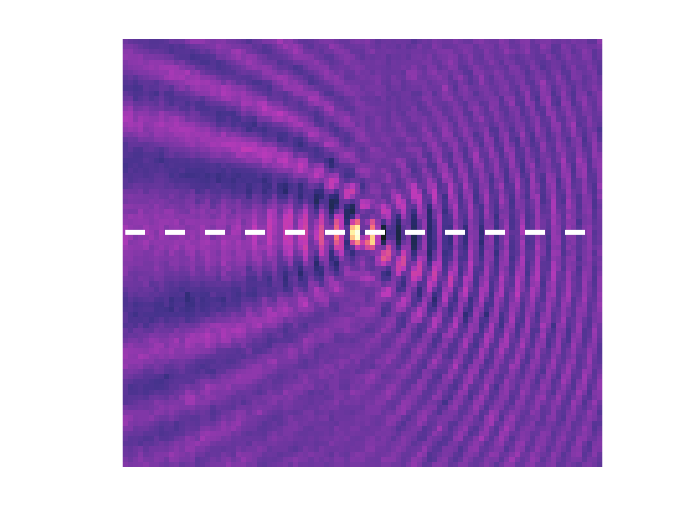

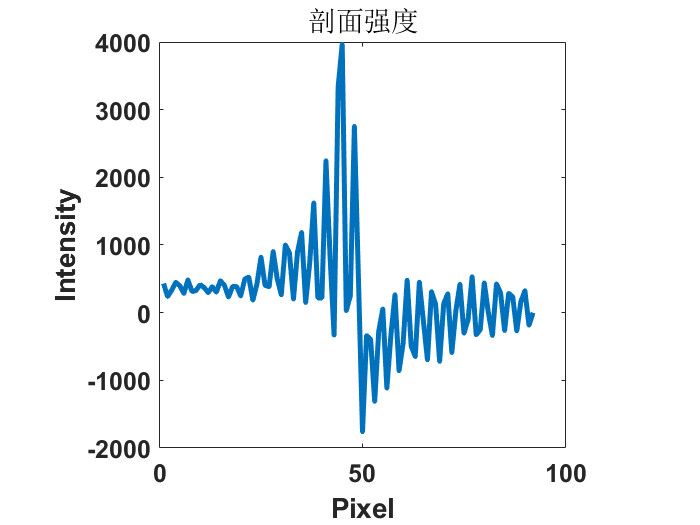

X = [1 93];
Y = [38 38];
int_spr = LineCut(I_spr,X,Y);

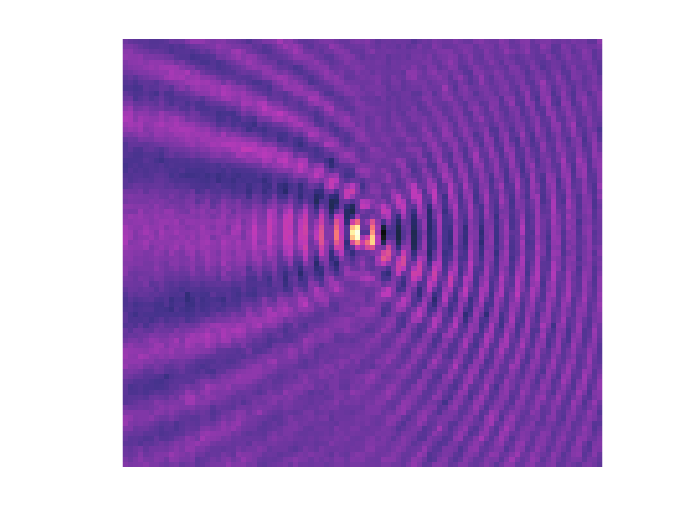

int_spr = int_spr/max(int_spr);
figure
imagesc(I_spr)
axis off
axis equal
colormap(sunglow)

% line([18 18+1000/73.8],[67 67],'color','white','linewidth',6)     % scalebar，长2um

## SPRM作图

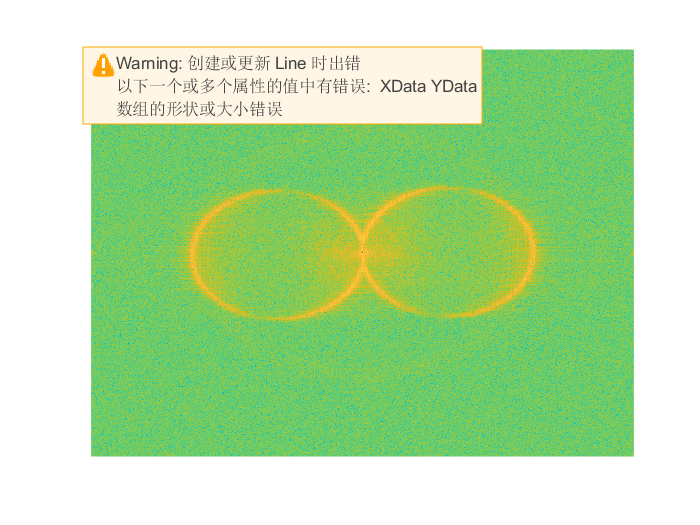

temp = findobj(gca,'type','line');      % 在以往作图的基础上修改
temp.YData = int_spr;

xlim([-5 98])
ylim([-0.5 1.1])
legend('SPRM')

## 读取peaks数据

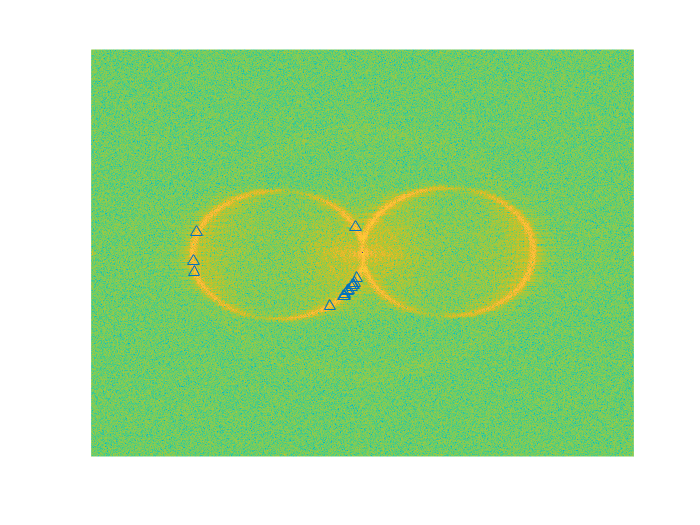

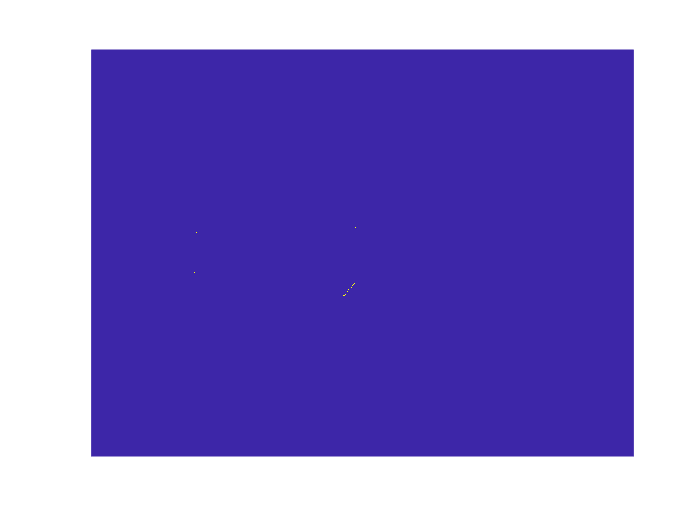

[center_raw,center_col,R,~] = findcircle(log(abs(F)),5,0,1);

peaks = [center_col,center_raw,R];
close

## 理想低通-f0 = 0.2

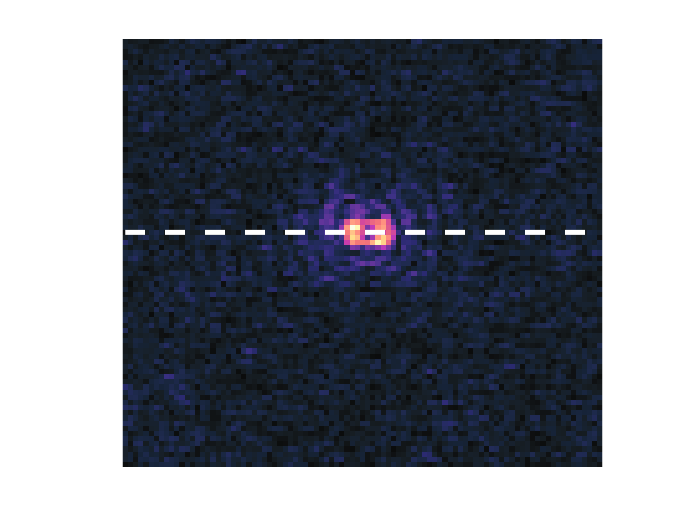

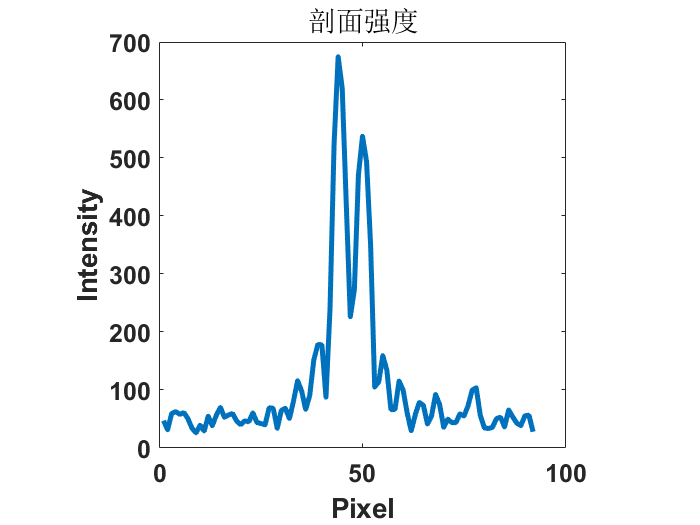

mask = EwaldMask(F,peaks,0.2,'I');
I_i1 = abs(ifftshift(ifft2(ifftshift(F.*mask))));
I_i1 = imcrop(I_i1,rectout);
int_i1 = LineCut(I_i1,X,Y);

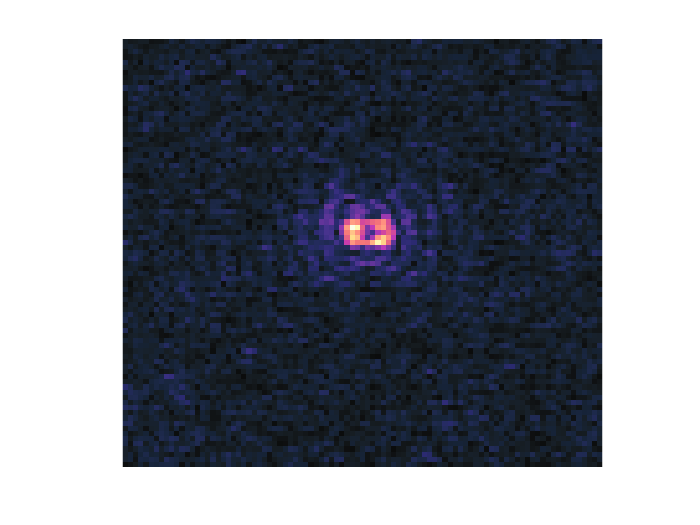

int_i1 = int_i1/max(int_i1);
figure 
imagesc(I_i1)
axis off
axis equal
colormap(sunglow)

## 理想低通-f0 = 0.2作图

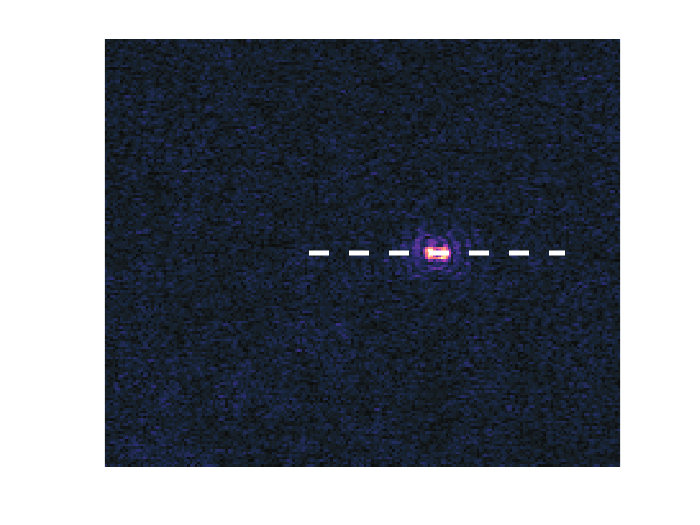

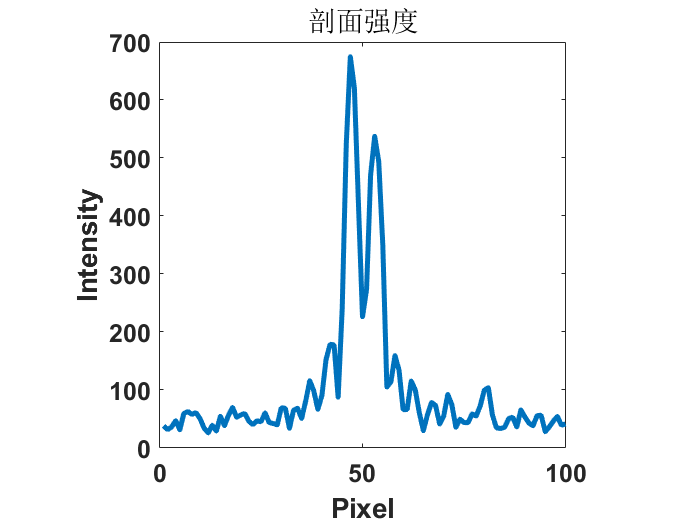

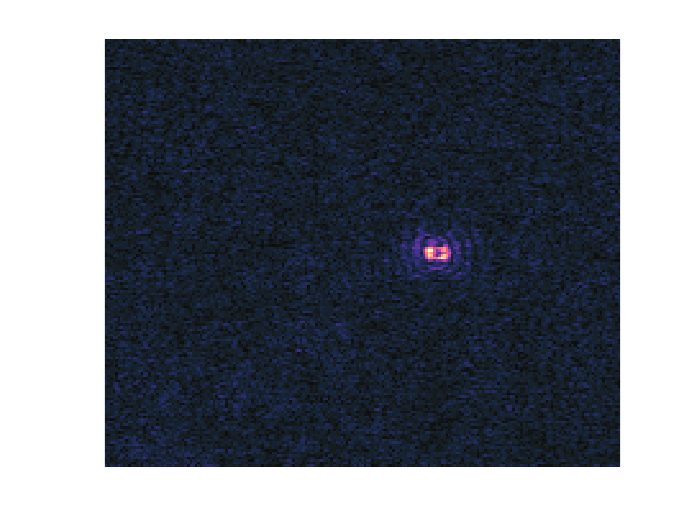

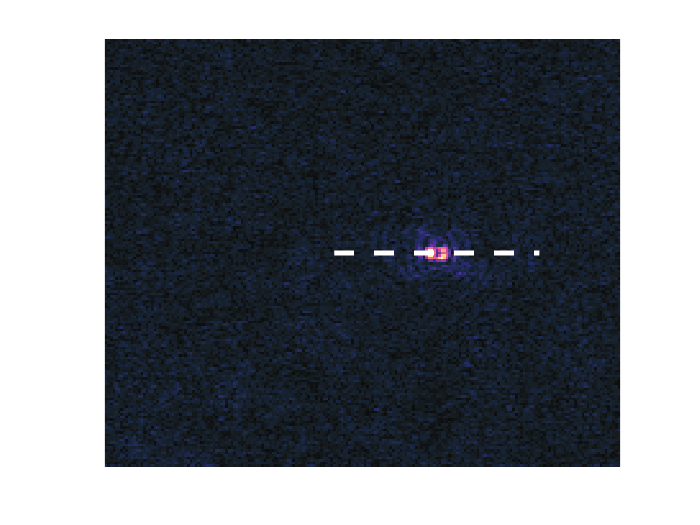

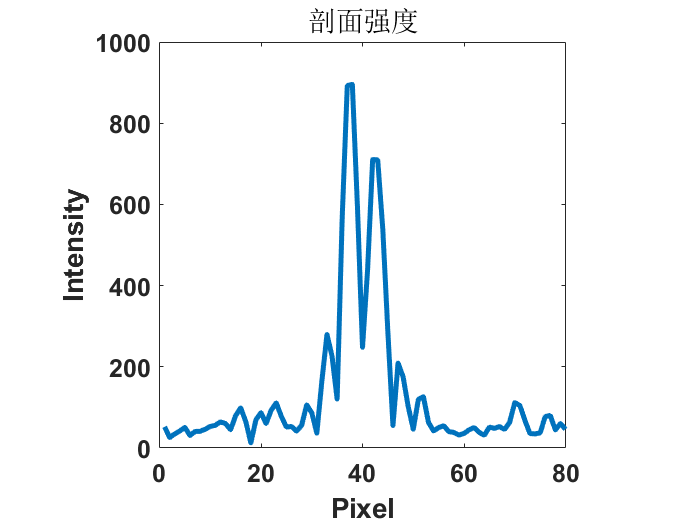

temp = findobj(gca,'type','line');      % 在以往作图的基础上修改
temp.YData = int_i1;
legend('ideal\_f_0 = 0.2')
xlim([-10 111])
ylim([0 1.2])

## 高斯-f0 = 0.2

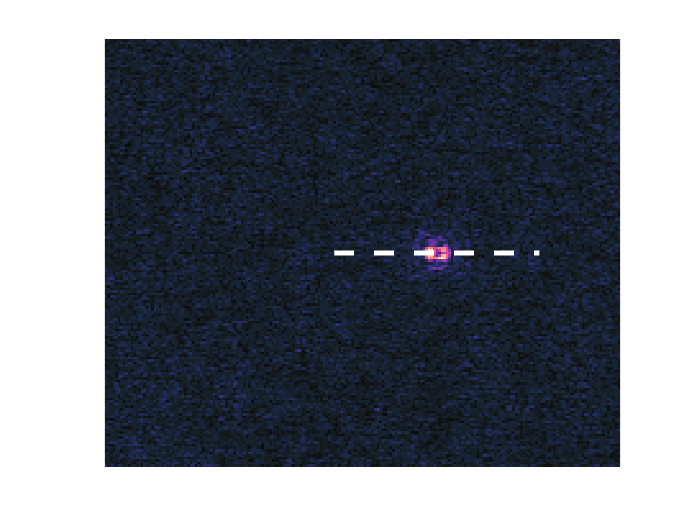

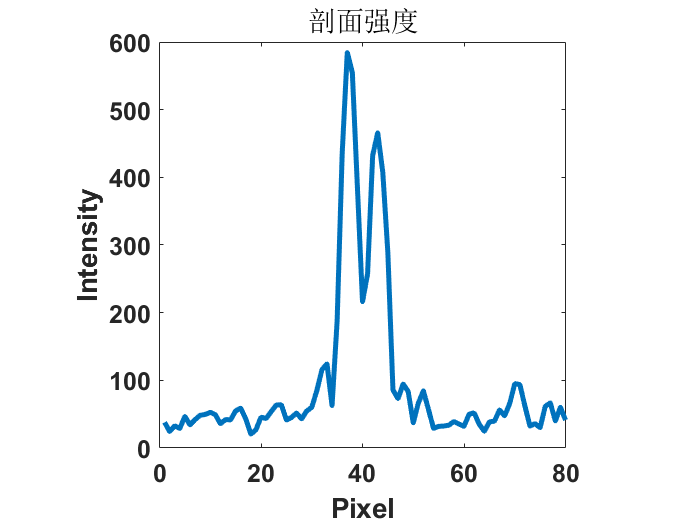

mask = EwaldMask(F,peaks,0.2,'G');
I_g2 = abs(ifftshift(ifft2(ifftshift(F.*mask))));
I_g2 = imcrop(I_g2,rectout);
int_g2 = LineCut(I_g2,X,Y);

int_g2 = int_g2/max(int_g2);
figure 
imagesc(I_g2)
axis off
axis equal
colormap(sunglow)

## 高斯-f0 = 0.2作图

temp = findobj(gca,'type','line');      % 在以往作图的基础上修改
temp.YData = int_g2;
legend('Gaussian\_f_0 = 0.2')
xlim([-10 111])
ylim([0 1.2])

## 定义归一化函数

function norml_I = normalization(I)
    max_num = max(I(:));
    min_num = min(I(:));
    norml_I = (I - min_num)/(max_num - min_num);
end